## Stillbilder

clear
selection ="boat.png";
image = double(imread(selection))+1;

[x,y] = size(image);

p_single = distribution2d(image);
H_single = entropyOfDistribution(p_single);

#### Parentropi horisontellt


$$H\left(X_{i,j} ,X_{i+1,j} \right)$$


p_hori = distribution2d_pair(image,[0 1]);
H_horizontal_pair = entropyOfDistribution(p_hori);

#### Parentropi vertikalt


$$H\left(X_{i,j} ,X_{i,j+1} \right)$$


p_vert = distribution2d_pair(image,[1 0]);
H_vertical_pair = entropyOfDistribution(p_vert);

#### Betingad


$$\left.H\left(X_{i+1,j} \right|X_{i,j} \right)$$


H_hori_cond = H_horizontal_pair - H_single;

 H(Xi,j+1 | Xi,j) 

H_vert_cond = H_vertical_pair - H_single;

## Entropier samlat

disp('Entropi')

Entropi


H_single

H_single = 7.1238


disp('Parentropi horisontellt')

Parentropi horisontellt


H_horizontal_pair

H_horizontal_pair = 12.0285


disp('Parentropi vertikalt')

Parentropi vertikalt


H_vertical_pair

H_vertical_pair = 11.7924


disp('Betingad entropi horisontellt')

Betingad entropi horisontellt


H_hori_cond

H_hori_cond = 4.9048


disp('Betingad entropi vertikalt')

Betingad entropi vertikalt


H_vert_cond

H_vert_cond = 4.6687

#### Huffmankodning


$$Y_{i,j} =X_{i,j} -P_{i,j}$$


l_single = huffman(p_single)

l_single = 7.1468


% Koda skillnader:
P_hori = padshift(image,[0 1],128);
P_vert = padshift(image,[1 0],128);
P_diag = padshift(image,[1 1],128);

% minshift av skilladen mellan originalet och den offsetade
Y1 = minshift2d(image - P_hori);
Y2 = minshift2d(image - P_vert);
Y3 = minshift2d(image - (P_vert + P_hori - P_diag));

%%
p_Y1 = distribution2d(Y1);
p_Y2 = distribution2d(Y2);
p_Y3 = distribution2d(Y3);

disp('Entropier: horisontellt, vertikalt och viktat')

Entropier: horisontellt, vertikalt och viktat


H_Y1 = entropyOfDistribution(p_Y1)

H_Y1 = 5.2050

H_Y2 = entropyOfDistribution(p_Y2)

H_Y2 = 4.9696

H_Y3 = entropyOfDistribution(p_Y3)

H_Y3 = 4.8649


disp('Huffman utan prediktion')

Huffman utan prediktion


l_single

l_single = 7.1468


disp('Huffman horisontellt')

Huffman horisontellt


l_Y1 = huffman(p_Y1)

l_Y1 = 5.2417


disp('Huffman vertikalt')

Huffman vertikalt


l_Y2 = huffman(p_Y2)

l_Y2 = 5.0064


disp('Huffman viktad')

Huffman viktad


l_Y3 = huffman(p_Y3)

l_Y3 = 4.8968

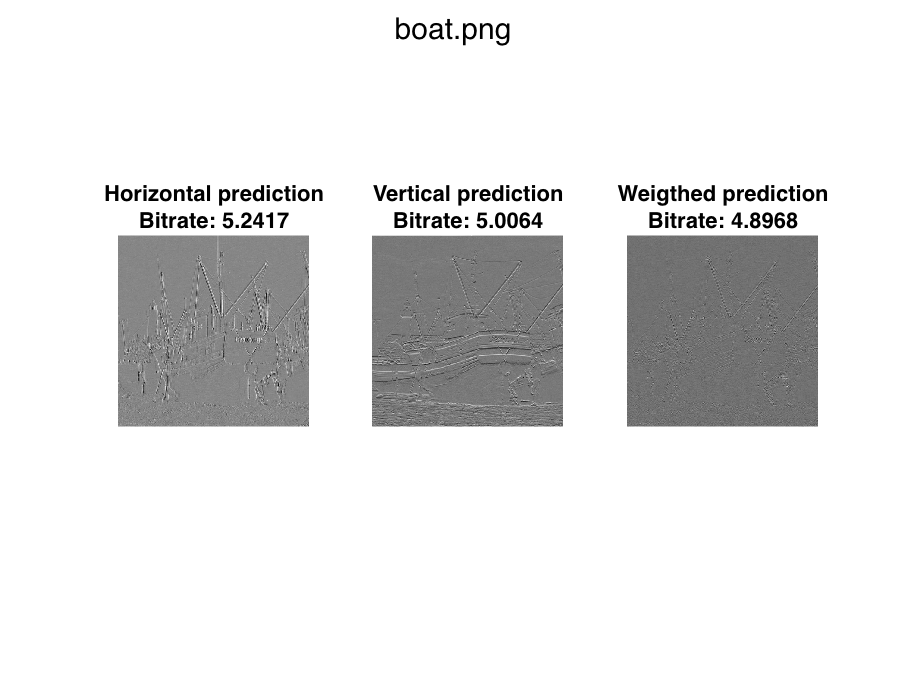


% Figures of predition errors

figure;
subplot(1,3,1);
imshow(Y1 / max(max(Y1)))
title({
    ('Horizontal prediction')
    ['Bitrate: ' num2str(l_Y1)] ...
    });

subplot(1,3,2);
imshow(Y2 / max(max(Y2)))
title({
    ('Vertical prediction')
    ['Bitrate: ' num2str(l_Y2)] ...
    });

subplot(1,3,3);
imshow(Y3 / max(max(Y3)))
title({
    ('Weigthed prediction')
    ['Bitrate: ' num2str(l_Y3) ] ...
    });

% den här buggar i live-script..
sgtitle(selection);